# V768 - Measuring Vision with Psychophysics

## Lab 5 - Adaptive Methods

In this lab, ...

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Explain the motivations for the development of adaptive methods.

- Describe the differences between an experiment using an adaptive staircase method and an experiment using the method of constant stimuli.

### Questions

- Include and write a caption for the figure in ...

- ...

We're going to install a fitting package for fitting psychometric functions. We have been using lsqcurvefit, but that won't work well for data from staircases because we don't have equal numbers of trials per point along the psychometric curve.  This package will take that into account.

!git clone https://github.com/wichmann-lab/psignifit

Cloning into 'psignifit'...
remote: Enumerating objects: 417, done.        
remote: Counting objects:   0% (1/116)        
remote: Counting objects:   1% (2/116)        
remote: Counting objects:   2% (3/116)        
remote: Counting objects:   3% (4/116)        
remote: Counting objects:   4% (5/116)        
remote: Counting objects:   5% (6/116)        
remote: Counting objects:   6% (7/116)        
remote: Counting objects:   7% (9/116)        
remote: Counting objects:   8% (10/116)        
remote: Counting objects:   9% (11/116)        
remote: Counting objects:  10% (12/116)        
remote: Counting objects:  11% (13/116)        
remote: Counting objects:  12% (14/116)        
remote: Counting objects:  13% (16/116)        
remote: Counting objects:  14% (17/116)        
remote: Counting objects:  15% (18/116)        
remote: Counting objects:  16% (19/116)        
remote: Counting objects:  17% (20/116)        
remote: Counting objects:  18% (21/116)        
remote: Counting obj

addpath("psignifit")

## The Staircase Method

The staircase method allows the experimenter to efficiently measure a perceptual threshold by adaptively adjusting the stimulus level based on the observer's recent performance.  This method often reduces the number of trials that an observer needs to perform.

#### How does this procedure work?

The most common staircase approach is the "two down, one up" staircase.  The way this works for a forced choice **detection task** (like the 2AFC contrast sensitivity experiment we did last week) is that if you are correct twice in a row the stimulus level decreases by one step and if you are wrong the stimulus level increases by one step.  

PICTURE

This works slightly differently for a **discrimination task** (like the orientation discrimination task we will complete today). For example, in a 2IFC orientation discrimination task, you would be asked to report whether the second interval was more clockwise or counterclockwise than the first interval.  Here the "one up, two down" would be based on your choice of clockwise or counterclockwise.   If you report that one trial is counterclockwise, the stimulus level increases by one step. If you report that two trials in a row clockwise, the stimulus level decreases by one step.

PICTURE

You might notice that this only really captures half of the points you might want to measure in an orientation discrimination experiment.  

**What about the orientations that are counter-clockwise?**  Usually for these kinds of experiments, the staircases are completed in pairs, one staircase that starts clockwise and one that starts counter-clockwise.  Their rules for adjusting the stimulus level across trials work in opposite ways.  The staircase that starts clockwise follows the rule that if you report that two trials in a row clockwise, the stimulus level decreases by one step and if you report one trial counter clockwise, the stimulus level increases by one step.  The staircase that starts counter-clockwise follows the rule that if you report that two trials in a row counter-clockwise, the stimulus level increases by one step,  and if you report one trial clockwise, the stimulus level decreases by one step.

## Part A.  Simulating an orientation discrimination experiment

Let us begin with a simulation.  Suppose you are simulating a orientation discrimination experiment.  

### Step 1. Choose parameters for your simulation.

You can use a psychometric curve to simulate performance on this task.  The first step is to choose a set of parameters for the psychometric curve.

% define psychometric function
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

mu = 0;
sigma = 3;
guess_rate = 0;
lapse_rate = 0;
params = [mu,sigma,guess_rate,lapse_rate];

### Step 2. Visualize the psychometric curve.

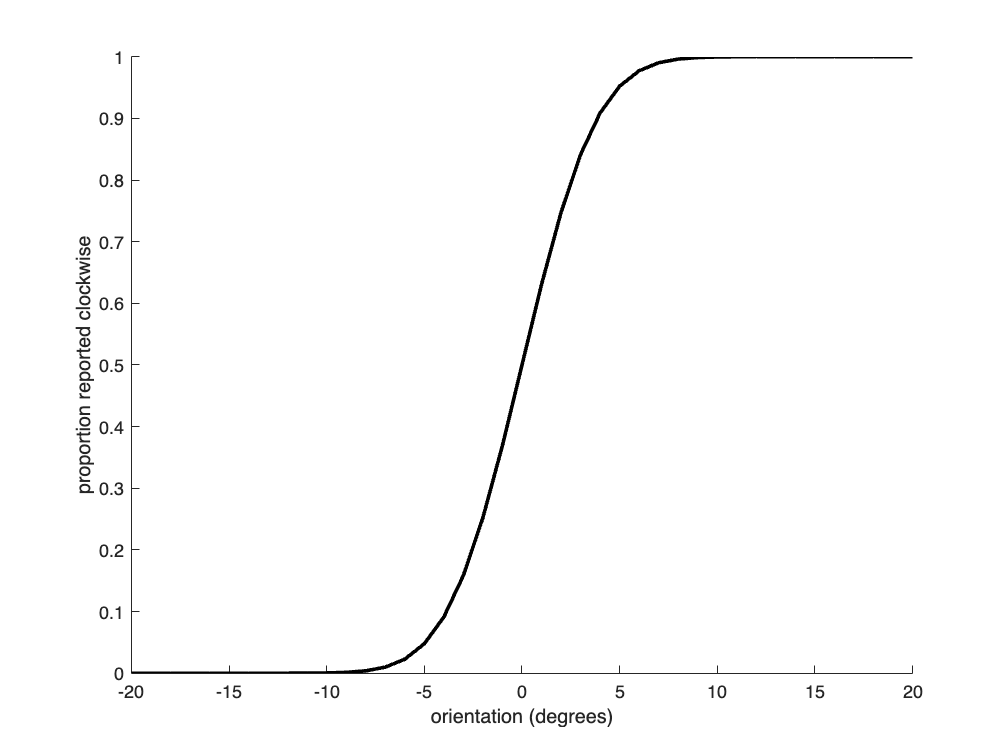

orientation_axis = -20:20;
prob_axis = psyfxn(params,orientation_axis);
figure();
plot(orientation_axis,prob_axis,'k','LineWidth',2);
xlabel('orientation (degrees)'); ylabel('proportion reported clockwise');
box off;

drawnow;

### Step 3. Simulate trials using the staircase method.

Now we will simulate trials using a one-up, two-down staircase.  For the staircase simulation, we will simulate one trial at a time.  This is because the orientation presented on a trial is dependent on the previous orientations presented and performance.  

nTrialsPerStaircase=60;
initial_orientation = 12;
staircase_step = 1; % degrees

% set up vectors for staircase.
orientation_levels_staircase = nan(nTrialsPerStaircase,1);
orientation_levels_staircase(1) = initial_orientation;
trials_staircase = nan(nTrialsPerStaircase,1);

counter = 0;
for ii=1:nTrialsPerStaircase

    % simulate current trial
    p=psyfxn(params,orientation_levels_staircase(ii));
    trials_staircase(ii) = binornd(1,p);

    % generate next trial
    if ii < nTrialsPerStaircase    
        if trials_staircase(ii) ==1 % chose clockwise
            counter = counter+1;
            if counter == 2
                orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii)-staircase_step;
                counter = 0; % reset
            else                    
                orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii);
            end
        else  % chose counter-clockwise
            orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii)+staircase_step;
            counter = 0; % reset
        end

    end

end

### Step 4. Visualize simulated staircase.

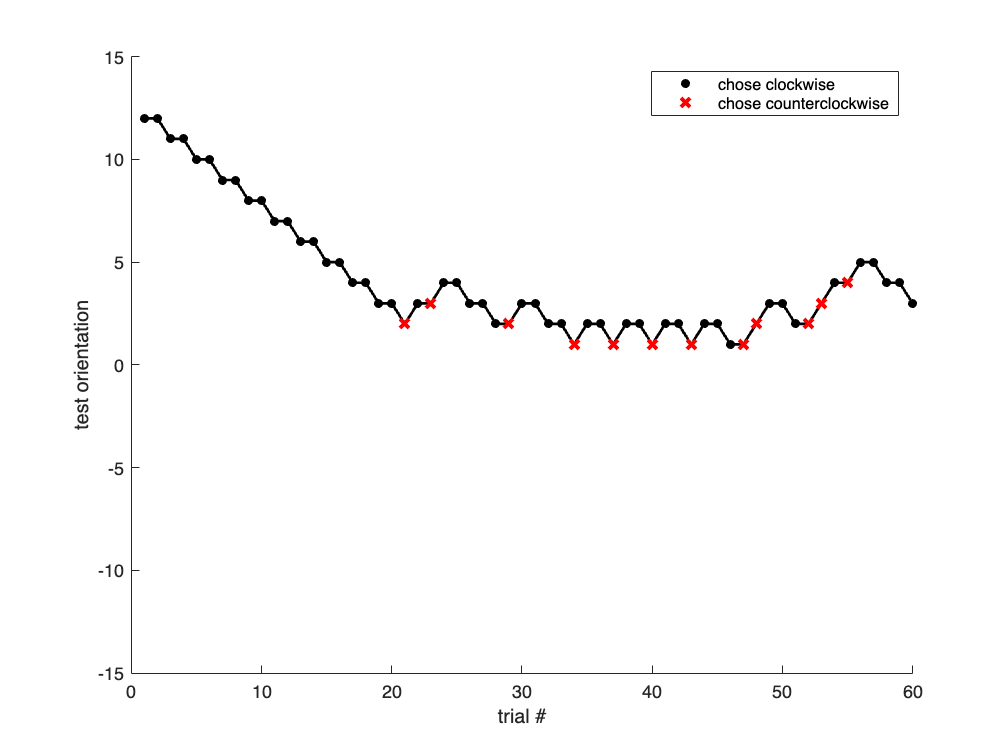

trialNo = 1:nTrialsPerStaircase;
figure();
plot(trialNo,orientation_levels_staircase,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase==1),orientation_levels_staircase(trials_staircase==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase==0),orientation_levels_staircase(trials_staircase==0),'rx','MarkerSize',7,'LineWidth',2)

box off;
xlabel('trial #'); ylabel('test orientation');
ylim([-15,15])
legend('','chose clockwise','chose counterclockwise');

drawnow;

### Step 5.  Simulate the second staircase

Recall that staircases for discrimination tasks are usually performed in pairs. Notice in the figure above that the staircase does not often go below 0 degrees.  This second staircase will provide data for the lower part of the graph.

% set up vectors for staircase.
initial_orientation = -12;
orientation_levels_staircase_2 = nan(nTrialsPerStaircase,1);
orientation_levels_staircase_2(1) = initial_orientation;
trials_staircase_2 = nan(nTrialsPerStaircase,1);

counter = 0;
for ii=1:nTrialsPerStaircase

    % simulate current trial
    p=psyfxn(params,orientation_levels_staircase_2(ii));
    trials_staircase_2(ii) = binornd(1,p);

    % generate next trial
    if ii < nTrialsPerStaircase    
        if trials_staircase_2(ii) == 0 % chose counter-clockwise
            counter = counter+1;
            if counter == 2
                orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii)+staircase_step;
                counter = 0; % reset
            else                    
                orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii);
            end
        else  % chose counter-clockwise
            orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii)-staircase_step;
            counter = 0; % reset
        end

    end

end


And now we can visualize both staircases.

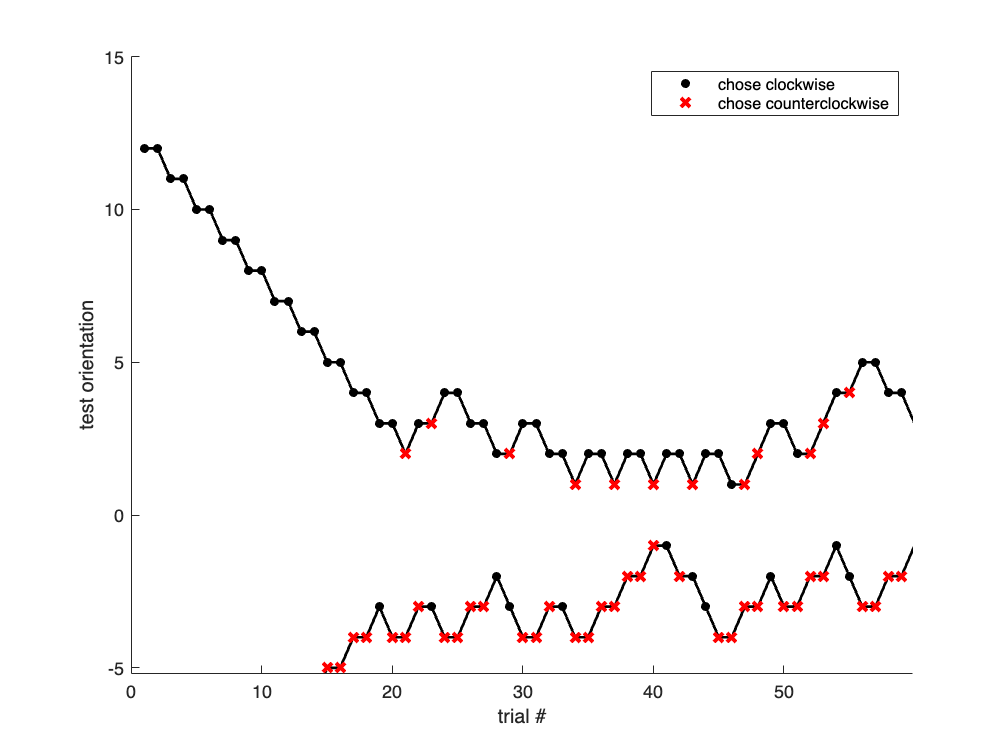

trialNo = 1:nTrialsPerStaircase;
figure();
plot(trialNo,orientation_levels_staircase,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase==1),orientation_levels_staircase(trials_staircase==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase==0),orientation_levels_staircase(trials_staircase==0),'rx','MarkerSize',7,'LineWidth',2)
plot(trialNo,orientation_levels_staircase_2,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase_2==1),orientation_levels_staircase_2(trials_staircase_2==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase_2==0),orientation_levels_staircase_2(trials_staircase_2==0),'rx','MarkerSize',7,'LineWidth',2)

box off;
xlabel('trial #'); ylabel('test orientation');
ylim([-15,15])
legend('','chose clockwise','chose counterclockwise');

drawnow;

### Step 6. Analyze the results of the simulation.

Even though we have collected this data in a somewhat different way than the method of constant stimuli, we can still use the psychometric function approach to analyze the data.  

**Note**:  Historical papers using staircases will sometimes compute the average stimulus values from the "last n reversals" to measure threshold.  This is no longer common practice and should be avoided.

simulated = array2table([[orientation_levels_staircase;orientation_levels_staircase_2],[trials_staircase; trials_staircase_2]],...
    "VariableNames",{'orientation_level','response'});
simulation_results = grpstats(simulated,"orientation_level");
simulation_results = renamevars(simulation_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prop_clockwise"]);
simulation_results.Properties.RowNames = {};
disp(simulation_results)

    orientation_level    n_trials    prop_clockwise
    _________________    ________    ______________

           -12               2                0    
           -11               2                0    
           -10               2                0    
            -9               2                0    
            -8               2                0    
            -7               2                0    
            -6               2                0    
            -5               2                0    
            -4              12                0    
            -3              17          0.29412    
            -2              11          0.36364    
            -1               4              0.5    
             1               6          0.16667    
             2              16             0.75    
             3              12          0.83333    
             

**Now let's fit the psychometric curve and plot the data and the fitted curve.**

figure();

% set up the data for the psignifit package.
data = [simulation_results.orientation_level, ...
    simulation_results.prop_clockwise.*simulation_results.n_trials,...
    simulation_results.n_trials];

% set up fitting options
options             = struct;   % initialize as an empty struct
options.sigmoidName = 'norm';   % choose a cumulative Gaussian as the sigmoid
options.expType     = 'YesNo';   % choose YesNo as the paradigm of the experiment
options.fixedPars = [nan,nan,nan,nan,0]; % Fix the "beta" parameter which is a weird thing to do with priors...

% fit the data
result = psignifit(data,options);
staircase_fits = getStandardParameters(result.Fit,'norm');
fprintf('mu = %.2f, sigma = %.2f, gamma = %.2f, lambda = %.2f', staircase_fits(1:4))

mu = 0.01, sigma = 3.26, gamma = 0.00, lambda = 0.00

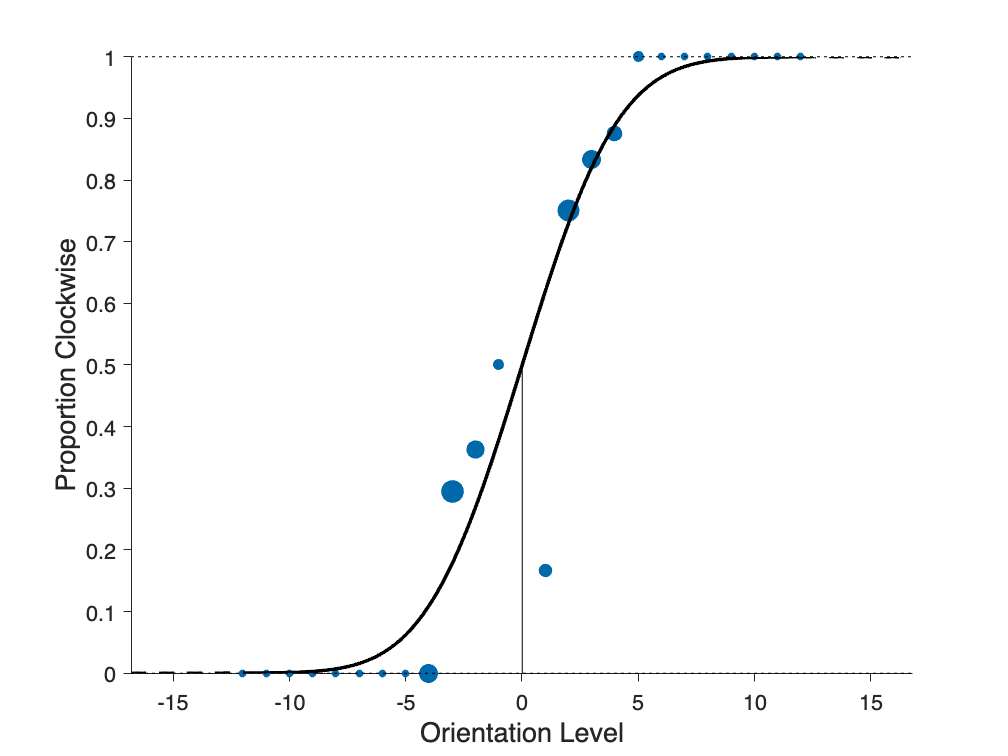

% plot the data + fit
plotOptions = struct;
plotOptions.xLabel         = 'Orientation Level'; % X-Axis label
plotOptions.yLabel         = 'Proportion Clockwise';% Y-Axis label
plotOptions.fontSize       = 12;               % Tick Font size
plotPsych(result,plotOptions);

drawnow;

## Part B. Simulating orientation discrimination 

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "TODO", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes (TODO) trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("adaptive-methods", "data");
if ~exist(data_dir, 'dir')
    error("PsychoPy data folder not found. Try changing your " + ...
        "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id+ "*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_05-adaptive-methods_2025-02-09_19h50.12.686.csv


#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
expt_data(:,remove) = [];

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 132


### Step 3. Analyze your data

For this experiment, the stimulus was a grating. The grating orientation varied across stimulus presentations.

For each trial, PsychoPy saved the stimulus orientation and the response direction.  The stimulus orientation was reported in degrees relative to vertical (e.g., 5 degrees represents 5 degrees clockwise from vertical, -10 degrees represents 10 degrees counter-clockwise from vertical. The responses were stored as string values with clockwise as 'cw' and counter-clockwise 'ccw'.

% stash the stimulus orientation and response
stimulus_orientation = expt_data.staircase_intensity;
response_dir = expt_data.response;

% convert the response key to 1 for clockwise and -1 for counterclockwise
% (to match stimulus location)
response = double(strcmp(response_dir,'cw'));

#### Determine whether responses were correct or incorrect

There are two ways for the responses to be correct: (1) if the stimulus was present clockwise and the person reported it clockwise, (2) if the stimulus was presented counter-clockwise and the person reported it counter-clockwise

% determine whether responses were correct or incorrect
resp_correct = (stimulus_orientation)>0 == response;

% display overall performance
fprintf('overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

overall percentage correct = 75.76%


#### Visualize the two interleaved staircases.

During the experiment you were performing ***interleaved*** trials from two staircases.  What we mean by interleaved is that we switched between two staircases during the experimental block, sometimes performing a trial from the first staircase and sometimes from the second staircase.

Let's plot the orientation level of the second grating on each trial to make this more clear.

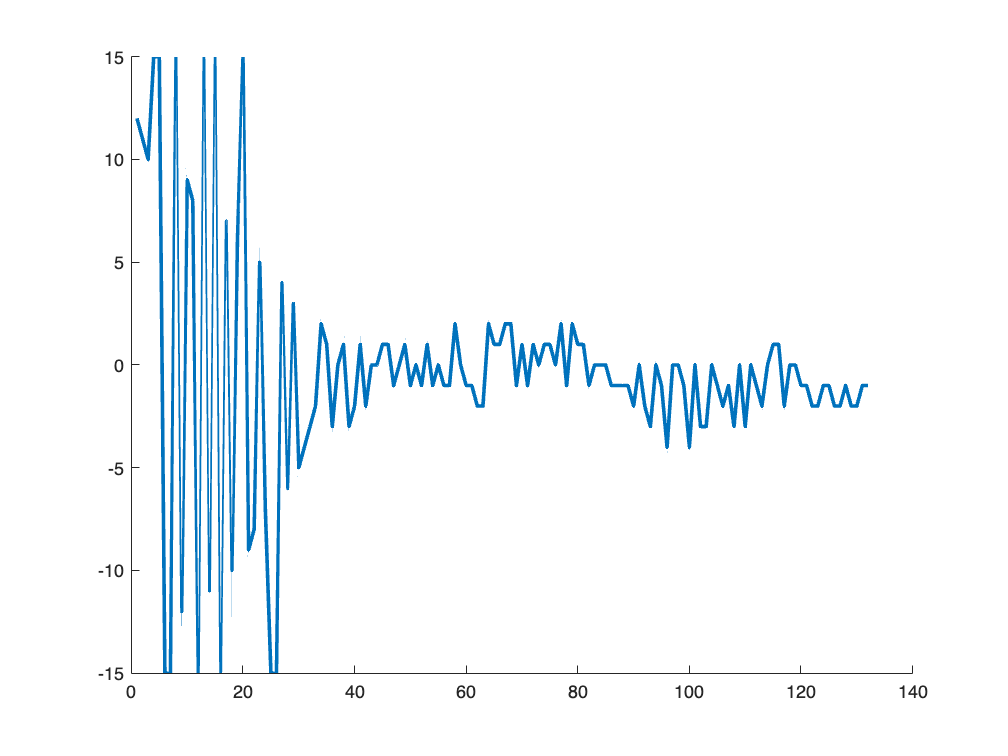

figure(); 
plot(stimulus_orientation,'LineWidth',2)
box off;

drawnow;

To make these staircases look more like the visualization of our simulations, we have to plot the two staircases separately.

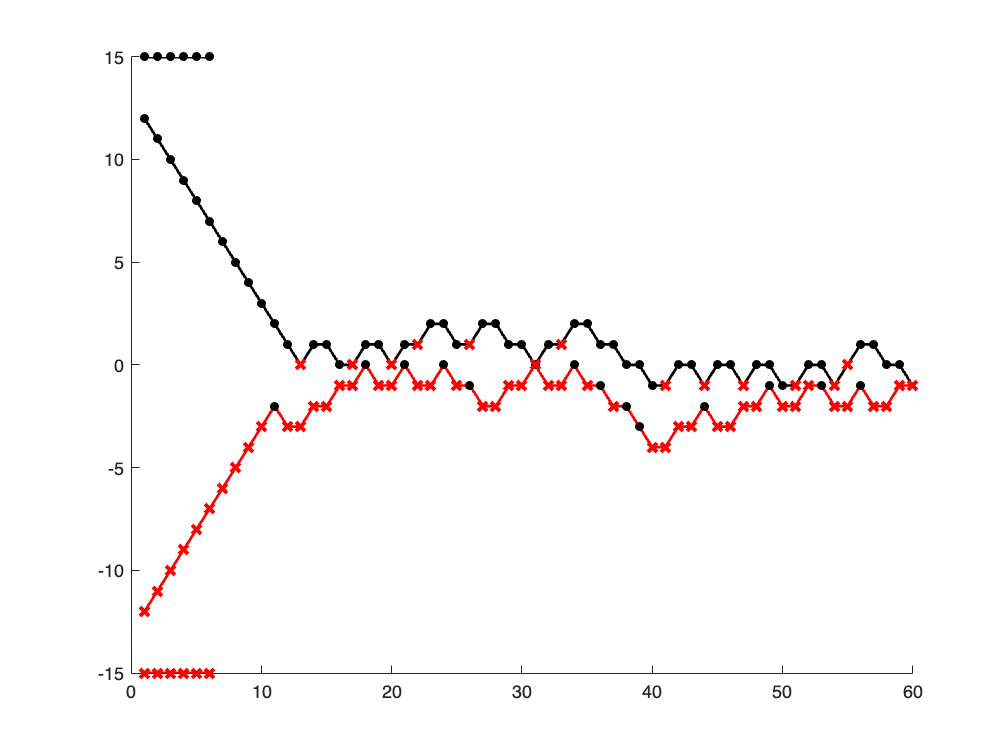

whichStaircase = expt_data.staircase_label;

idx_cw = strcmp(whichStaircase,'cw');
idx_ccw = strcmp(whichStaircase,'ccw');
idx_hi = strcmp(whichStaircase,'hi');
idx_lo = strcmp(whichStaircase,'lo');

idx_resp = expt_data.staircase_response==1;

figure(); hold on;
plot(stimulus_orientation(idx_cw),'k','LineWidth',1.5)
plot(stimulus_orientation(idx_ccw),'r','LineWidth',1.5)
plot(stimulus_orientation(idx_hi),'k','LineWidth',2)
plot(stimulus_orientation(idx_lo),'r','LineWidth',2)

plot(expt_data.staircase_thisRepN(idx_resp),stimulus_orientation(idx_resp),'k.','MarkerSize',15)
plot(expt_data.staircase_thisRepN(~idx_resp),stimulus_orientation(~idx_resp),'rx','MarkerSize',7,'LineWidth',2)

drawnow;

#### Determine percentage correct per condition

% average across responses per contrast level
analysis_table = table(response, expt_data.staircase_intensity, ...
    'VariableNames',["response", "orientation"]);
expt_results = grpstats(analysis_table, ["orientation"]);
expt_results = renamevars(expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prop_clockwise"]);
expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
orientation_levels = unique(expt_results.orientation);
n_orientation = length(orientation_levels);

% display results   `
disp(expt_results)

    orientation    n_trials    prop_clockwise
    ___________    ________    ______________

        -15            6                0    
        -12            1                0    
        -11            1                0    
        -10            1                0    
         -9            1                0    
         -8            1                0    
         -7            1                0    
         -6            1                0    
         -5            1                0    
         -4            3                0    
         -3            8            0.125    
         -2           16           0.1875    
         -1           28             0.25    
          0           23          0.78261    
          1           17          0.82353    
          2            7                1    
          3            1                1    
          4            

#### Fit and plot performance in the form of a psychometric curve.

figure();

% set up the data for the psignifit package.
data = [expt_results.orientation, ...
    expt_results.prop_clockwise.*expt_results.n_trials,...
    expt_results.n_trials];

% set up fitting options
options             = struct;   % initialize as an empty struct
options.sigmoidName = 'norm';   % choose a cumulative Gaussian as the sigmoid
options.expType     = 'YesNo';   % choose YesNo as the paradigm of the experiment
options.fixedPars = [nan,nan,nan,nan,0]; % Fix the "beta" parameter which is a weird thing to do with priors...

% fit the data
result = psignifit(data,options);

staircase_fits = getStandardParameters(result.Fit,'norm');
fprintf('mu = %.2f, sigma = %.2f, gamma = %.2f, lambda = %.2f', staircase_fits(1:4))

mu = -0.58, sigma = 1.41, gamma = 0.00, lambda = 0.00

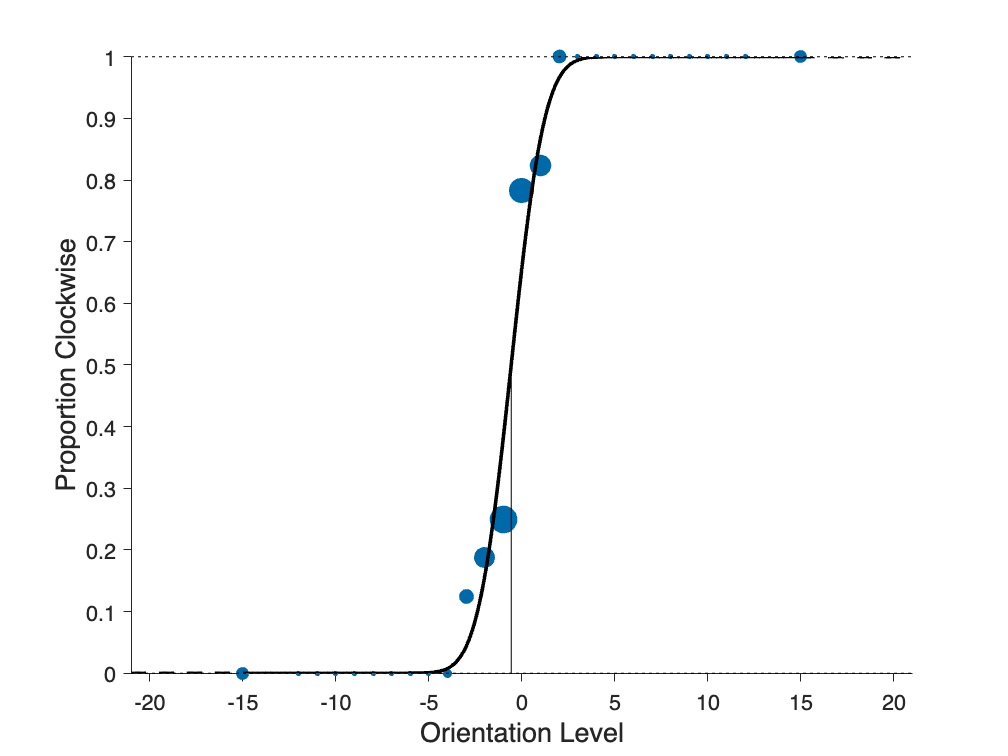

% plot the data + fit
plotOptions = struct;
plotOptions.xLabel         = 'Orientation Level'; % X-Axis label
plotOptions.yLabel         = 'Proportion Clockwise';% Y-Axis label
plotOptions.fontSize       = 12;               % Tick Font size
plotPsych(result,plotOptions);

drawnow

**What do you see?** 